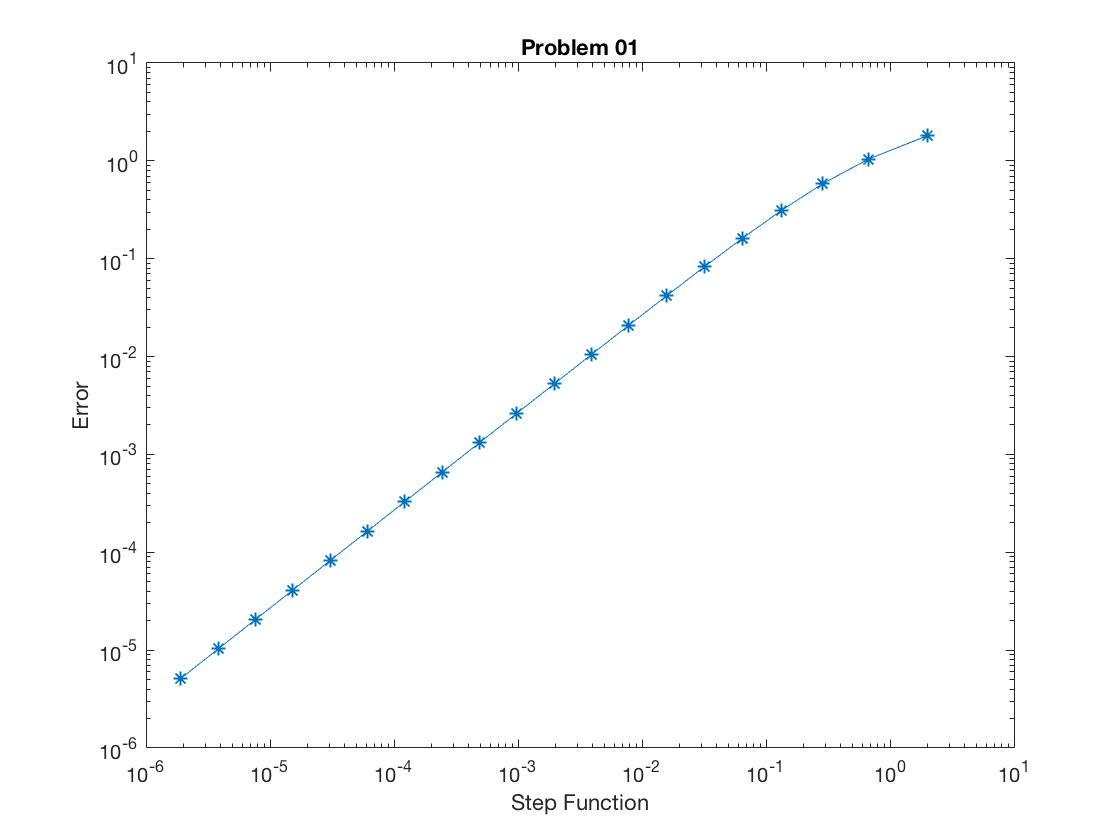

%Number 01
f=@(t,y) y-t^2+1;
fExact=(3)^2-exp(2)/2;
k=1:20;
N=2.^k;
y=0.5;

for i=1:length(N)
 t=linspace(0,2,N(i));
 h(i)=t(2)-t(1);
 for j=2:length(t)
 y(j)=y(j-1)+h(i)*f(t(j-1),y(j-1));
 end
 err(i)=abs(fExact-y(end));
end

%Graph Making
loglog(h,err,'-*');
title('Problem 01');
xlabel('Step Function');
ylabel('Error');

% Number 02
tspan = [0 2];
fExact = @(t) (t + 1)^2 - exp(t)/2;
[t, y] = ode45(f, tspan, y);
fprintf('Approximate y(2): %.8f\n', y(end));

Approximate y(2): 40.81334021


fprintf('Number of timesteps: %d\n', length(t));

Number of timesteps: 45


fprintf('Error in the Approx. y(2): %.8f\n', y(end) - (fExact(2)));

Error in the Approx. y(2): 35.50786826
